# ber

bpsk fsk en css van https://ieeexplore.ieee.org/abstract/document/7797659

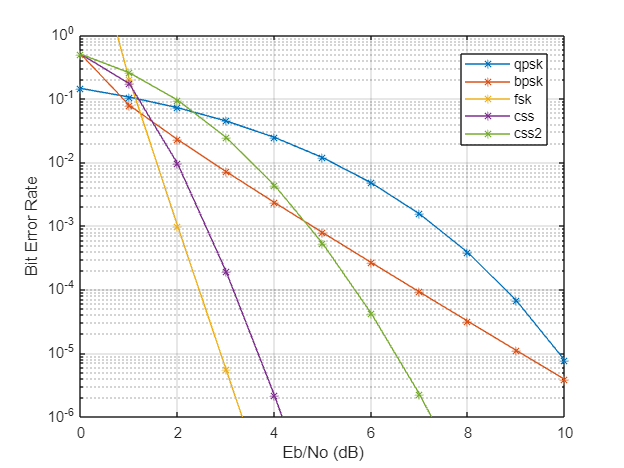

k=10;%bits per symbol aka SF

EbN0=0:10;
p_bsk=qfunc(sqrt(2*EbN0));
p_fsk=((2^k)/4)*qfunc(sqrt(k*EbN0));
p_css=(1/2)*qfunc(1.28*sqrt(k*EbN0)-sqrt(k)*1.28+0.4);
p_css2=qfunc((log(k)/log(12))/sqrt(2)*EbN0);%log12(k)=log(k)/log(12)
%https://www.researchgate.net/publication/366847808_Analysis_Of_The_Energy_Per_Bit_To_Noise_Power_Spectral_Density_And_Operating_System_Margin_For_Lora-Based_Wireless_Sensor_Network

ber=berawgn(EbN0,"psk",4,"diff");
figure
semilogy(EbN0',ber,'-*')
hold on
semilogy(EbN0',p_bsk,'-*')
hold on
semilogy(EbN0',p_fsk,'-*')
hold on
semilogy(EbN0',p_css,'-*')
hold on
semilogy(EbN0',p_css2,'-*')
legend({'qpsk','bpsk','fsk','css','css2'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')

grid on
ylim([1e-6, 1])